t=0:0.00001:0.3;
x1=(exp(-3*t)).*(0.2*sin(2*pi*400*t));
x2=1.2+(exp(-1.5*t)).*(1.1*sin(2*pi*40*t+pi/6));
x3=(exp(-5*t)).*(0.8*sin(2*pi*75*t+pi/3));
X=x1+x2+x3

X =     2.4428    2.4521    2.4613    2.4705    2.4797    2.4888    2.4979    2.5070    2.5160    2.5250    2.5339    2.5428    2.5517    2.5604    2.5691    2.5778    2.5864    2.5949    2.6033    2.6117    2.6199    2.6281    2.6363    2.6443    2.6522    2.6601    2.6678    2.6755    2.6831    2.6905    2.6979    2.7051    2.7122    2.7193    2.7262    2.7330    2.7396    2.7462    2.7526    2.7589    2.7651    2.7712    2.7771    2.7829    2.7885    2.7941    2.7994    2.8047    2.8098    2.8148


plotting the signal

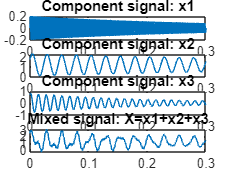


subplot(4,1,1);
plot(t,x1);title('Component signal: x1');
subplot(4,1,2);
plot(t,x2);title('Component signal: x2');
subplot(4,1,3);
plot(t,x3);title('Component signal: x3');
subplot(4,1,4);
plot(t,X);title('Mixed signal: X=x1+x2+x3');

Loading the data

image_test =  'C:\Users\unity\source\repos\Year two\clas\ECNG 3020 Heart Rate\frame9.jpg';
image1 = imread(image_test);
image1d = double(image1);

using the ICA algorithm

mdln = rica(X,3);

Error using featlearn.utils.InputValidator.validateX
Predictors must be specified as a numeric, real matrix.

Error in ReconstructionICA (line 197)
            X = featlearn.utils.InputValidator.validateX(X);

Error in rica (line 68)
    obj = Recon